# **Secant Method**

**Secant Method** is a numerical method for solving an equation in one unknown. It is quite similar to Regular Falsi method. One drawback of Newton’s method is that it is necessary to evaluate f´(x) at various points, which may not be practical for some choices of f(x). The secant method avoids this issue by using a finite difference to approximate the derivative. As a result, root of f(x) is approximated by a secant line through two points on the graph of f(x), rather than a tangent line through one point on the graph.

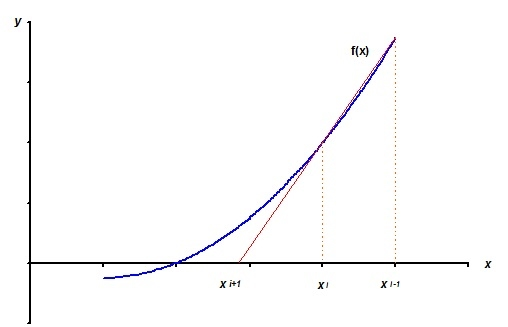

In Secant method root of f(x) is approximated by a secant line through two points on the graph of f(x), rather than a tangent line through one point on the graph.Since a secant line is defined using two points on the graph of f(x), as opposed to a tangent line that requires information at only one point on the graph, it is necessary to choose two initial iterates $x_0$ and $x_1$. Then, as in Newton’s method, the next iterate $x_2$ is then obtained by computing the x-value at which the secant line passing through the points ($x_0$, f($x_0$)) and ($x_1$, f($x_1$)) has a y-coordinate of zero. This yields the equation

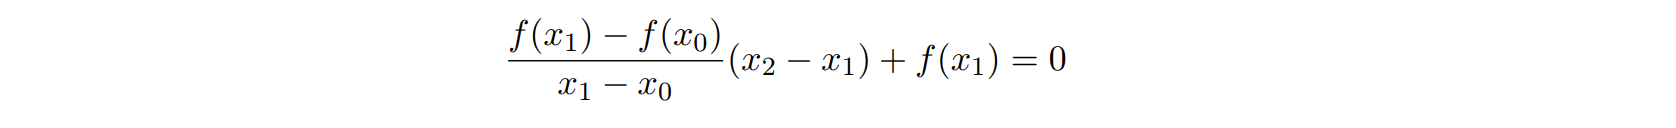

which gives $x_2$ as 

As we can see above that the equation for new estimate is same as in Regula falsi Mehtod but unlike in regula falsi method we don't check if the inital two estimates statisfy the condition that function sign at both points should be opposite.

### **Step 1 : Defining the Function **

First step of this method is to define the function and we have to give two initial value of the function$x_0$and $x_1$ .For ensuring the accuracy of the root, we have to define the accuracy(**accuracy**) .

Here we will take function as input from user which will be treated as a string and stored into  **f_input** variable.Using inline function (ignoring warning )  we have turned it into a vector which can be calculated by Matlab.

Here we have defined accuracy as approximate relative error which can be representated as 

### 
$$\textrm{accuracy}=|\frac{x_n -x_{n-1} }{x_n }|$$


For simplification of our calculation we didnot converted the accuracy into % .So if we want 1% accuracy here the value of accuracy will be 0.001

f_input = input("Enter f(x) = ","s");           %Function of variable x
f = inline(f_input);                %using anonymous function instead of inline function
x_0 = input ( "Value of first guess (x(0)) =");
x_1 = input ( "Value of second guess (x(1)) = ");
accuracy = input ( "Value of required accuracy  =");

### **Step 2 : Checking Functional Value at point a and b**

In this step we will use **if** statement to check that is any of the initial guess of the root actually a root of the function and use **return** statement to stop executing rest of the matlab script.  

if (f(x_1) == 0 || f(x_0) == 0 )
    fprintf("Boundary value is one of the roots\n")
    return 
end


### **Step 3 : Initialize the values **

First we have to inititalize some required values.To start counting our number of interation, we assigned  i= 0 , and  we will find our root untill we get our required accuracy ,so we will initialize the error value as height value as infinity

i = 0;
error = inf ;

### **Step 4 : Let's start iteration **

- For iteration process we will use while loop as our iteration will continue untill we achieve our required accuracy.

- Next accepted root according to secant  is   $\textrm{root}=x_1 -\frac{f\left(x_1 \right)\left(x_1 -x_0 \right)}{f\left(x_1 \right)-f\left(x_0 \right)}$

- Now we will calculate our error value $\textrm{error}=|\frac{x_1 -\textrm{root}}{x_1 }|$

- As we have to continiously change the value of $x_1$ and $x_0$ to find the root ,we have to increment the each root value by one .So next $x_0 =x_1$ and next $x_1 =\textrm{root}$.

- As first iteration is completed we will increase the value of **i** by one which is our number of iteration.

- As we want to print our iteration result as table, so firstly we have printed heading of the table just only when the value of iteration is 1. Then we have printed all other values of current iteration  

while abs (error) > accuracy
    root = x_1 -(f(x_1)*(x_1-x_0))/(f(x_1)-f(x_0));
    error = abs((x_1-root)/(x_1));
    
    x_0 = x_1;
    x_1 = root;
    
    i=i+1;
    if i == 1
        fprintf("Iteration \t Root \t\t Error ");
    end
 
    fprintf('\n %d \t \t %f\t %f', i,root,error);
end

### Step 5 : Printing Results 

Finally we will print our result with required accuracy 

fprintf("The root of the function is %f",root);